# Electrophysiology main bench

clear;clc;close all;

cd('D:\Electrophysiology\Matdelane\');
addpath(genpath('matnwb'));
addpath(genpath('matdelane'));
generateCore();

nwbPath = "data\";

nwbFiles = {dir(nwbPath).name};
nwbFiles = nwbFiles(endsWith(nwbFiles, ".nwb"));

disp("Toolbox setup done.");

Toolbox setup done.


xunits = load("data\xunits.mat", "xunits");
xunits = xunits.xunits;

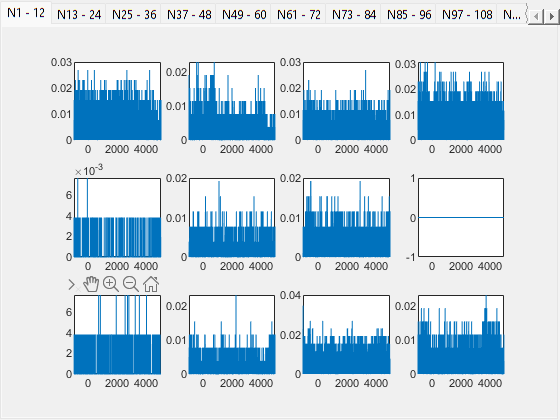

% b2l - b2o2 - b2o4 unit by unit, area by area

hFig = figure('Name', 'Single unit analysis / OGLO passive', 'NumberTitle', 'off');
hT = uitabgroup('Parent', hFig);
hTabs = cell(1);
cnt = 1;

for i = 1:10

    title_ = "N" + num2str(i*12 - 11) + " - " + num2str(i*12);
    hTabs{cnt} = uitab('Parent', hT, 'Title', title_);
    axes('Parent', hTabs{cnt});
    t = linspace(-1000, 5000, 6000);
    y = squeeze(mean(xunits{3, 1}.sigsb2l, 1));

    for ij = 1:12
    
        subplot(3, 4, ij);
        plot(t, y(i*12 -12 + ij, :));

    end

    cnt = cnt + 1;

end

areas = ["V1", "V2", "V3d", "V3a", "V4", "MT", "MST", "TEO", "FST", "FEF", "PFC"];
areasN = zeros(1, 11);
areasMap = containers.Map();

for i = 1:size(xunits,  1)

    for j = 1:size(xunits, 2)

        try
            
            xarea = strsplit(xunits{i, j}.area, ",");
            skipFlag = 0;

        catch

            skipFlag = 1;
            continue;

        end

        if ~skipFlag

            for k = 1:size(xarea, 2)
            
                xarea_ = strsplit(xarea{k}, " ");
                xarea_ = xarea_{end};
                nunits_ = floor(size(xunits{i, j}.sigsb2l, 2)/size(xarea, 2));
                
                try

                    areasMap(xarea_) = areasMap(xarea_) + nunits_;

                catch

                    areasMap(xarea_) = nunits_;

                end

            end

        end

    end

end

for i = 1:11

    k_ = areas(i);
    areasN(i) = areasMap(k_);
    fprintf(">Area %s :%d good units\n", k_, areasN(i));

end

>Area V1 :543 good units
>Area V2 :441 good units
>Area V3d :230 good units
>Area V3a :230 good units
>Area V4 :308 good units
>Area MT :214 good units
>Area MST :110 good units
>Area TEO :166 good units
>Area FST :20 good units
>Area FEF :168 good units
>Area PFC :639 good units



areasN(3) = areasN(3) + areasMap('V3');
areasN(5) = areasN(5) + areasMap('DP');

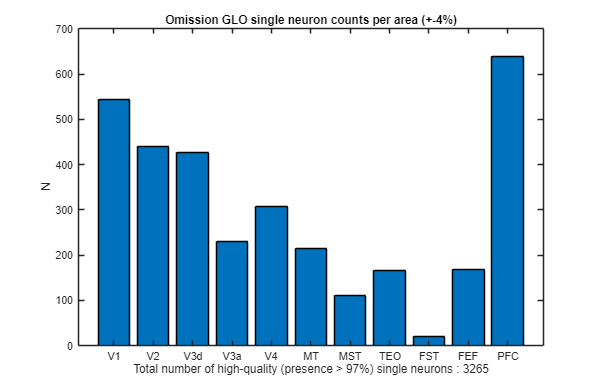

figure("Position", [0 0 1700 1100]);

bar(areas, areasN);title("Omission GLO single neuron counts per area (+-4%)");
ylabel("N");
xlabel("Total number of high-quality (presence > 97%) single neurons : " + num2str(sum(areasN)));

xunits = cell(16, 4);

for ik = 1:size(nwbFiles, 2)

    nwbFile = nwbPath + nwbFiles{ik};
    nwb = nwbRead(nwbFile);

    for jk = 1:numel(nwb.general_devices.keys())

        xunits{ik, jk} = jOGLOUnits(nwb, jk-1);

    end

end

> Session sub-C31o_ses-230630

->Total correct trials: 220
-> AAAB(1) = 10, XAAAB(2) = 50, BBBA(3) = 10, XBBBA(4) = 50, XRRRR(5) = 100 

--> (1) AAAB habituation : 10 

--> (2) AAAB omission. omission chance : 0.320000 

--> (2) AAAB : 43 

--> (2) AXAB : 7 

--> (2) AAXB : 6 

--> (2) AAAX : 3 

--> (3) BBBA habituation : 10 

--> (4) BBBA omission. omission chance : 0.420000 

--> (4) BBBA : 44 

--> (4) BXBA : 6 

--> (4) BBXA : 7 

--> (4) BBBX : 8 

--> (5) RRRR omission. omission chance : 0.180000 

--> (5) RRRR : 93 

--> (5) RXRR : 7 

--> (5) RRXR : 2 

--> (5) RRRX : 9 
Area(s): PFC
1-2001-_
1-2001-_
1-2001-_
> Session sub-C31o_ses-230630

->Total correct trials: 220
-> AAAB(1) = 10, XAAAB(2) = 50, BBBA(3) = 10, XBBBA(4) = 50, XRRRR(5) = 100 

--> (1) AAAB habituation : 10 

--> (2) AAAB omission. omission chance : 0.320000 

--> (2) AAAB : 43 

--> (2) AXAB : 7 

--> (2) AAXB : 6 

--> (2) AAAX : 3 

--> (3) BBBA habituation : 10 

--> (4) BBBA omission. omission chance : 0.


save("data\xunits_conv.mat", "xunits", "-v7.3");

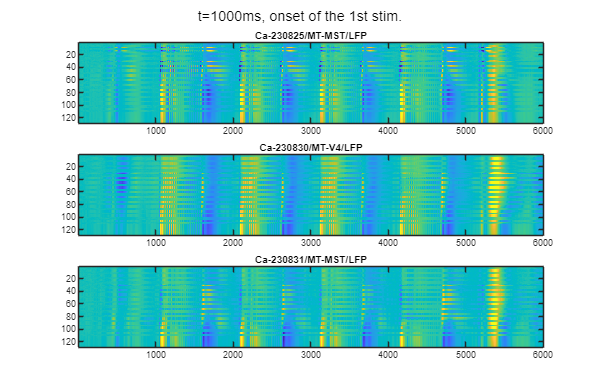

im1 = squeeze(mean(x1.sigsb2l(:, :, :), 1));
im2 = squeeze(mean(x2.sigsb2l(:, :, :), 1));
im3 = squeeze(mean(x3.sigsb2l(:, :, :), 1));

figure("Position", [0 0 1700 1100]);

subplot(3, 1, 1);
imagesc(im1);
clim([-100 100]);
title("Ca-230825/MT-MST/LFP");

subplot(3, 1, 2);
imagesc(im2);
clim([-100 100]);
title("Ca-230830/MT-V4/LFP");

subplot(3, 1, 3);
imagesc(im3);
clim([-100 100]);
title("Ca-230831/MT-MST/LFP");

sgtitle("t=1000ms, onset of the 1st stim.");

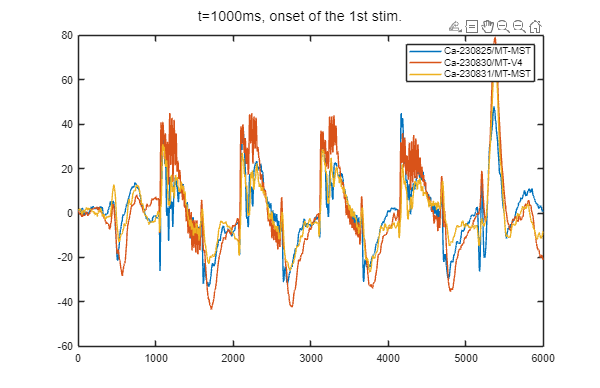

im1 = squeeze(mean(x1.sigsb2l(:, :, :), 1));
im2 = squeeze(mean(x2.sigsb2l(:, :, :), 1));
im3 = squeeze(mean(x3.sigsb2l(:, :, :), 1));

figure("Position", [0 0 1700 1100]);

subplot(1, 1, 1);
plot(mean(im1, 1), "DisplayName", "Ca-230825/MT-MST");
hold("on");
plot(mean(im2, 1), "DisplayName", "Ca-230830/MT-V4");
plot(mean(im3, 1), "DisplayName", "Ca-230831/MT-MST");

legend();

sgtitle("t=1000ms, onset of the 1st stim.");

a = jReceptiveFieldMap(nwb, 1);

photodiode = nwb.acquisition.get("photodiode_1_tracking").timeseries.get("photodiode_1_tracking_data").data;
mrk = nwb.intervals.get("rf_mapping_v2").start_time.data(end);

l1times = nwb.intervals.get("laser_1_empirical_decode").start_time.data(:);
l1freqs = nwb.intervals.get("laser_1_empirical_decode").vectordata.get("frequency").data(:);
l1level = nwb.intervals.get("laser_1_empirical_decode").vectordata.get("level").data(:);
l1types = nwb.intervals.get("laser_1_empirical_decode").vectordata.get("type").data(:);

unx1 = nwb.processing.get("convolved_spike_train").nwbdatainterface.get("convolved_spike_train_data").data;

unx5 = zeros(100, 69, 2000);
unx40 = zeros(100, 69, 2000);

cnt5 = 1;
cnt40 = 1;

for ia = 1:size(l1level, 1)

    idx2time = ceil(l1times(ia) * 1000);

    if l1freqs(ia) == 5

        unx5(cnt5, :, :) = unx1(:, idx2time-500+1:idx2time+1500);
        cnt5 = cnt5 + 1;

    elseif l1freqs(ia) == 40

        unx40(cnt40, :, :) = unx1(:, idx2time-500+1:idx2time+1500);
        cnt40 = cnt40 + 1;

    end

end

figure("Position", [0 0 1700 1100]);

subplot(2, 1, 1);
imagesc(squeeze(mean(unx5, 1)));
xline(500, "Color", [0 1 1]);
xline(1500, "Color", [1 1 0]);

title("Single unit convolved response. Onset of the laser is t = 1000ms. Top (5Hz) Bottom (40Hz)");
xlabel("time in ms");
ylabel("5Hz lazer all power levels");
clim([0 40]);

subplot(2, 1, 2);
imagesc(squeeze(mean(unx40, 1)));
xline(500, "Color", [0 1 1]);
xline(1500, "Color", [1 1 0]);
xlabel("time in ms");ylabel("40Hz lazer all power levels");
clim([0 40]);

## End